# ROTEIRO 3

## COMPLEXIDADE N^2

close all 
clc
clear

load audio_gravado.mat

filename = 'audio_gravado.wav';
audiowrite(filename,Y,FS);
clear y Fs

Y = Y(1:100)

Y = 1.0e-04 *

         0
         0
   -0.3052
         0
         0
         0
         0
   -0.3052
         0
         0


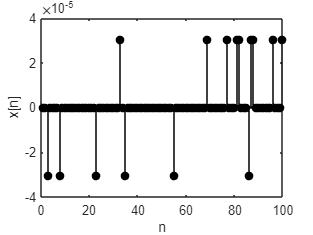

%%plotar grafico
figure
stem(Y,"filled",'k');
ylabel('x[n]');
xlabel('n');


















%criar sinal ficticio
N=100;
%frequecia e frequencia de amostragem
%calcular a frequencia que não esta no grid: vazamento espectral
f=1.1;
f=1;
fs=20;
%de manos pi a pi
W=2*pi*f/fs;
%vetor n 
n = 0:N-1;
x = sin(W*n);

%%plotar grafico
figure
stem(n,x,"filled",'k');
ylabel('x[n]');
xlabel('n');
ylim([-1.1,1.1]);


# Fazendo dft

%%achando matriz
%normalizando
DFT = dftmtx(N)*(1/N);
%%achando o espectro
X=DFT*x';

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches
the number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*)
for elementwise multiplication.

Related documentation


% Omega1=0: 2*pi/N: 2*pi/(N-1)/N;
Omega2 = linspace(0,2*pi*(N-1)/N,N)
omega = Omega2*fs;

%achando frequencia em hz
f_hz=omega/(2*pi);

%precisa separar em modulo e fase
figure;
stem(f_hz,abs(X),"filled",'k');
xlabel('Frequencia (Hz)')
ylabel('|X(\Omega)|')
%plotando de 0 a 2pi precisamos mapear as 100 amostras para espaço de 0 a
%(N-1)*


# MODIFICANDO ASPECTRO


Xabs = abs(X);
Xabs = Xabs(1:N/2+1);
Xabs(2:end) = Xabs(2:end)*2

%frequencia modificada
f_hz = f_hz(1:N/2+1);

figure;
stem(f_hz,Xabs,"filled",'k');
xlabel('Frequencia (Hz)')
ylabel('|X(\Omega)|')


## Fazendo DFT

%%achando matriz
%normalizando
DFT_modificado = dftmtx(N)*(1/N);
%%achando o espectro
X_modificado=DFT_modificado*x_modificado';


Omega_modificado = linspace(0,2*pi*(N-1)/N,N)
omega_modificado = Omega_modificado*fs;


%achando frequencia em hz
f_hz_modificado=omega_modificado/(2*pi);
f_hz_modificado = f_hz_modificado(1:N/2+1);

Xabs_modificado = abs(X_modificado);
Xabs_modificado = Xabs_modificado(1:N/2+1);
Xabs_modificado(2:end) = Xabs_modificado(2:end)*2

%precisa separar em modulo e fase
figure;
stem(f_hz_modificado,Xabs_modificado,"filled",'k');
xlabel('Frequencia (Hz)')
ylabel('|X(\Omega)|')
%plotando de 0 a 2pi precisamos mapear as 100 amostras para espaço de 0 a
%(N-1)*


## densidade espectral de frequencia

figure 
stem(f_hz,Xabs.^2,"filled",'k');
xlabel('Frequencia (Hz)')
ylabel('|X(\Omega)|')

## calculando pela fft

Xfft = fft(x);


